# 34.

A system is described by the difference equation

**y[n] = x[n] − 0.9y[n − 1] + 0.81y[n − 2]. (2.121)**

Using MATLAB determine and plot

(a) Impulse response of the system.

(b) Step response of the system.

(c) Identify the transient response and the steady-state response in (b).

**a**

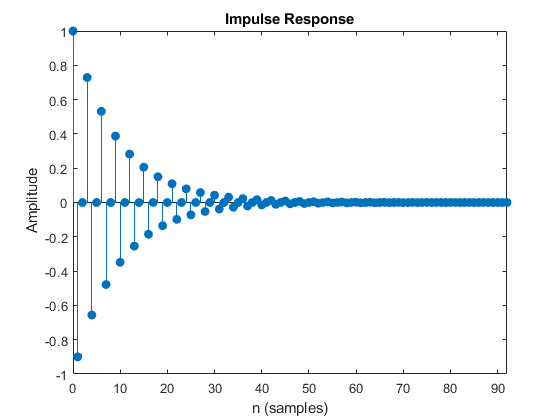

a = [1 0.9 0.81];
b = [1];

impz(b,a)

**b**

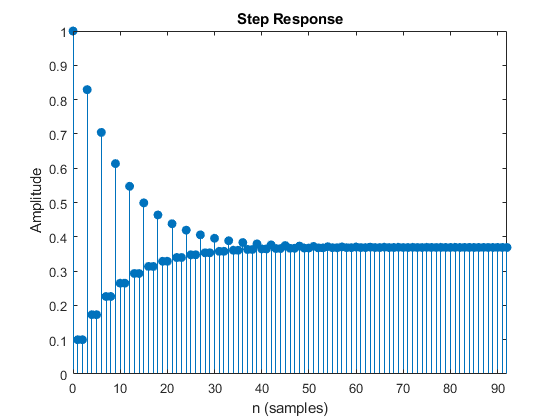

stepz(b,a);

**c**

For samples 0-55 can be classified as transient response which can be shown in plot as varying amplitude. While after that the the amplitude becomes constant and can be classified as steady state response. 

sysX = tf(b,a,0.01)

sysX =
 
          1
  ------------------
  z^2 + 0.9 z + 0.81
 
Sample time: 0.01 seconds
Discrete-time transfer function.



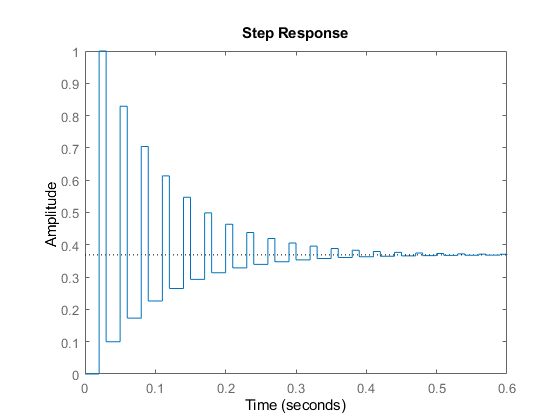

step(sysX)

stepinfo(sysX)

ans = struct with fields:
        RiseTime: 0
    SettlingTime: 0.3900
     SettlingMin: 0.1000
     SettlingMax: 1
       Overshoot: 171
      Undershoot: 0
            Peak: 1
        PeakTime: 0.0200
